# Spline cúbico, Matricial x 4 Puntos (theta2)

% puntos para spline, en tiemp de 1 a 4
Puntos=([(1:4)',theta2'])';
Puntos=Puntos(:);


## Construcción de matríz característica

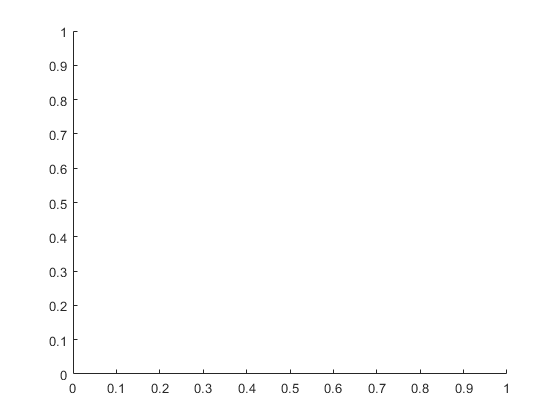

A0=[Puntos(1)^3,Puntos(1)^2,Puntos(1),1;Puntos(3)^3,Puntos(3)^2,Puntos(3),1];
A1=[Puntos(3)^3,Puntos(3)^2,Puntos(3),1;Puntos(5)^3,Puntos(5)^2,Puntos(5),1];
A2=[Puntos(5)^3,Puntos(5)^2,Puntos(5),1;Puntos(7)^3,Puntos(7)^2,Puntos(7),1];

A11=[3*Puntos(3)^2,2*Puntos(3),1,0,-3*Puntos(3)^2,-2*Puntos(3),-1,0];
A12=[3*Puntos(5)^2,2*Puntos(5),1,0,-3*Puntos(5)^2,-2*Puntos(5),-1,0];

A111=[6*Puntos(3),2,0,0,-6*Puntos(3),-2,0,0];
A222=[6*Puntos(5),2,0,0,-6*Puntos(5),-2,0,0];


A=[A0,0*A0,0*A0;0*A0,A1,0*A0;A0*0,A0*0,A2;A11,0,0,0,0;0,0,0,0,A12;A111,0,0,0,0;0,0,0,0,A222];

A=[A;3*Puntos(1)^2,2*Puntos(1),1,0,0,0,0,0,0,0,0,0];
A=[A;0,0,0,0,0,0,0,0,3*Puntos(7)^2,2*Puntos(7),1,0];
b=[Puntos(2);Puntos(4);Puntos(4);Puntos(6);Puntos(6);Puntos(8);0;0;0;0;0;0];

hold off

solv=A\b;

## Graficar y obtener tramos de polinomio

Para cada tramo encontrado en la solución, escribir el polinomio

entre los dos puntos del tramo correspondiente, con separacion 0.05

x=Puntos(1):0.05:(Puntos(3));
y=solv(1)*x.^3+solv(2)*x.^2+solv(3)*x+solv(4);
plot(x,y)
hold on

x1=Puntos(3):0.05:Puntos(5);
y1=solv(5)*x1.^3+solv(6)*x1.^2+solv(7)*x1+solv(8)

y1 =    2.023612921539830   2.133110984593080   2.234612291024866   2.327796355455972   2.412342692507183   2.487930816799286   2.554240242953060   2.610950485589297   2.657741059328775   2.694291478792281   2.720281258600602   2.735389913374520   2.739296957734820   2.731681906302287   2.712224273697704   2.680603574541859   2.636499323455536   2.579591035059512   2.509558223974587   2.426080404821529   2.328837092221135


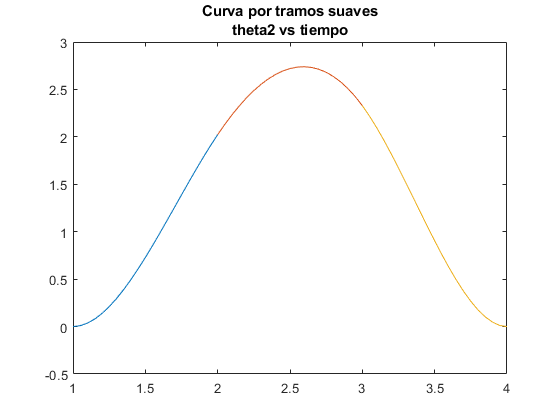

plot(x1,y1)
 
x2=Puntos(5):0.05:Puntos(7);
y2=solv(9)*x2.^3+solv(10)*x2.^2+solv(11)*x2+solv(12);

plot(x2,y2)

X2=[x,x1(2:end-1),x2];
Y2=[y,y1(2:end-1),y2];
title({'Curva por tramos suaves';'theta2 vs tiempo'})

hold off

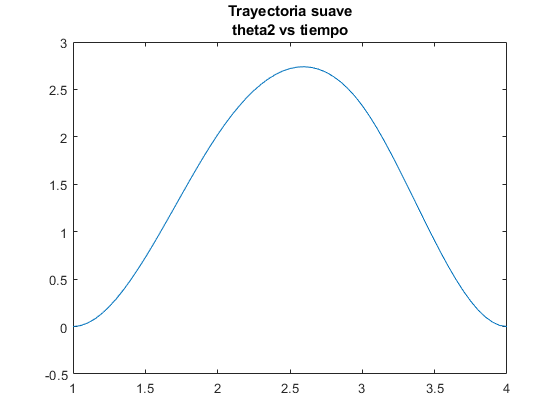

plot(X2,Y2)
title({'Trayectoria suave';'theta2 vs tiempo'})

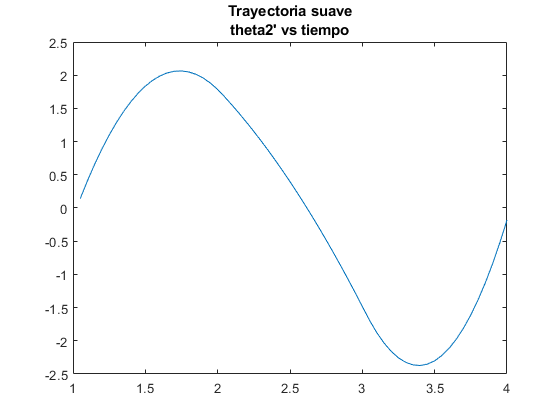


factor=length((1:4)')/length(Y1);
plot(X2(2:end),diff(Y2)/factor)
title({'Trayectoria suave';"theta2' vs tiempo"})

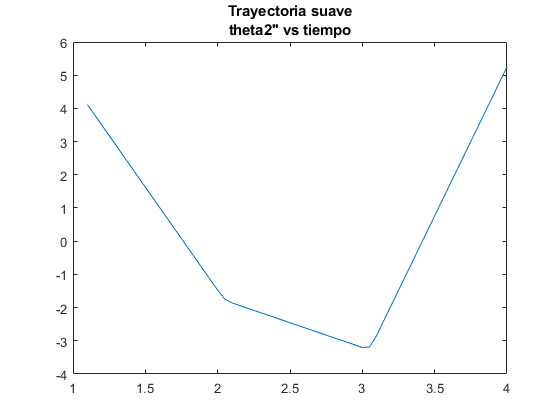


plot(X2(3:end),diff(diff(Y2))/(factor^2))
title({'Trayectoria suave';"theta2'' vs tiempo"})




% Programado por: Alfredo José Maussa Caballero.